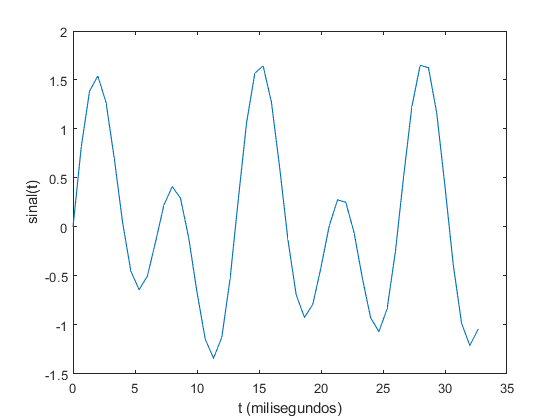

fs = 1500;
T = 1/fs;
tempoSinal = 1;
t = 0:T:tempoSinal; % (0:tempoSinal-1)*T

sinal = 0.7*sin(2*pi*80*t) + sin(2*pi*150*t);
plot(1000*t(1:50),sinal(1:50));
xlabel('t (milisegundos)')
ylabel('sinal(t)');

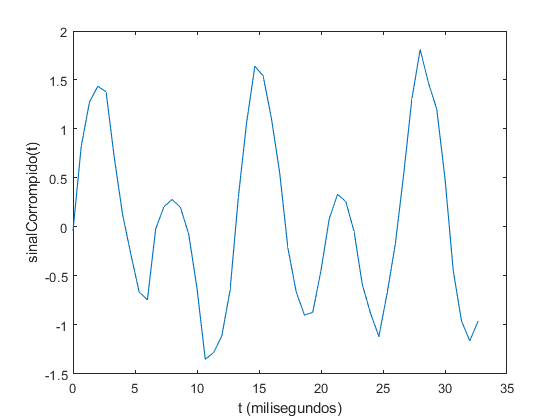


sinalCorrompido = sinal + 0.1*randn(size(t));
plot(1000*t(1:50),sinalCorrompido(1:50));
xlabel('t (milisegundos)');
ylabel('sinalCorrompido(t)');

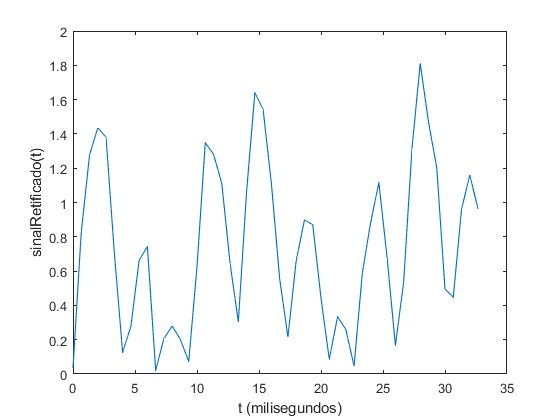

sinalRetificado = abs(sinalCorrompido);
plot(1000*t(1:50),sinalRetificado(1:50));
xlabel('t (milisegundos)');
ylabel('sinalRetificado(t)');

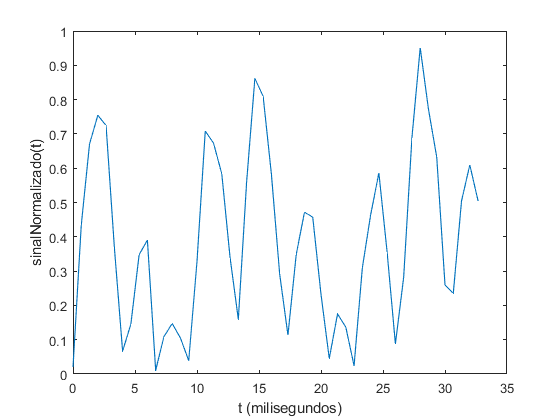

sinalNormalizado = sinalRetificado/max(abs(sinalRetificado));
plot(1000*t(1:50),sinalNormalizado(1:50));
xlabel('t (milisegundos)');
ylabel('sinalNormalizado(t)');




p(1:length(sinal)) = 0;
p(1:1/fs:end) = 1;

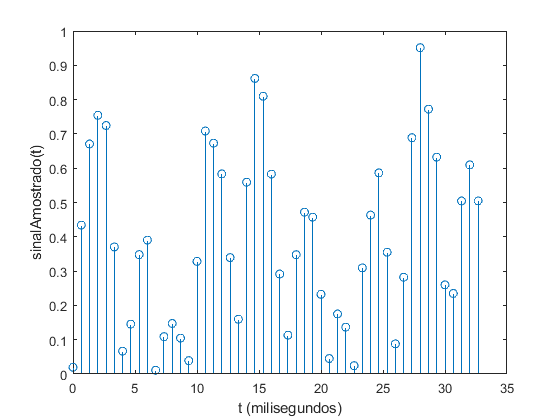

sinalAmostrado = p.*sinalNormalizado;
stem(1000*t(1:50),sinalAmostrado(1:50));
xlabel('t (milisegundos)');
ylabel('sinalAmostrado(t)');

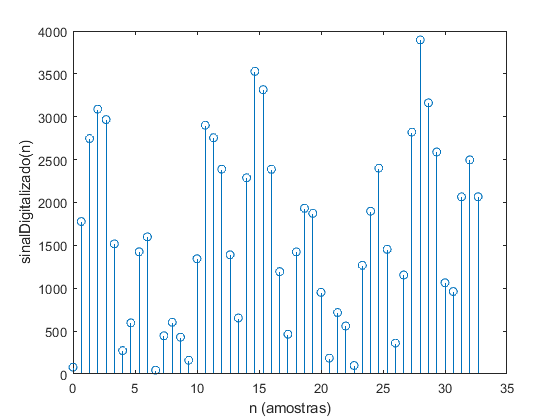

sinalDigitalizado = round(sinalAmostrado*((2^12)-1));
stem(1000*t(1:50),sinalDigitalizado(1:50));
xlabel('n (amostras)');
ylabel('sinalDigitalizado(n)');

sinalBinario = converte2binario(sinalDigitalizado);
sinalBinario(:,1:30)

ans =      0     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     0     0     1     1     1     1     0     0     0     0     0
     0     1     0     1     0     1     0     0     1     1     0     0     0     0     0     1     0     0     0     1     0     0     1     1     0     1     0     1     1     1
     0     1     1     0     1     0     0     1     0     1     0     0     1     0     0     0     1     1     0     0     1     0     0     0     0     0     0     0     1     1
     0     0     0     0     1     1     1     0     1     0     0     1     0     1     0     1     1     0     1     1     0     0     1     0     1     0     1     1     1     1
     0     1     1     0     1     1     0     0     1     0     0     1     0     1     1     0     0     1     0     0     1     1     1     1     0     1     1     1     1     0
     1     1     0     0     0     1     0     1     0     0     0     0     1     0     